# Figure S4B

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A038_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 15×5 cell array
    {'siEmi1 TAK'         }    {[2 3]}    {[  2 3]}    {[1]}    {[0]}
    {'siEmi1 CDK2i'       }    {[2 3]}    {[  4 5]}    {[1]}    {[0]}
    {'siEmi1 CDK2i+TAK'   }    {[2 3]}    {[  6 7]}    {[1]}    {[0]}
    {'siEmi1 CDK4/6i'     }    {[2 3]}    {[  8 9]}    {[1]}    {[0]}
    {'siEmi1 Control'     }    {[2 3]}    {[10 11]}    {[1]}    {[0]}
    {'siRif1 TAK'         }    {[4 5]}    {[  2 3]}    {[1]}    {[0]}
    {'siRif1 CDK2i'       }    {[4 5]}    {[  4 5]}    {[1]}    {[0]}
    {'siRif1 CDK2i+TAK'   }    {[4 5]}    {[  6 7]}    {[1]}    {[0]}
    {'siRif1 CDK4/6i'     }    {[4 5]}    {[  8 9]}    {[1]}    {[0]}
    {'siRif1 Control'     }    {[4 5]}    {[10 11]}    {[1]}    {[0]}
    {'siControl TAK'      }    {[6 7]}    {[  2 3]}    {[1]}    {[0]}
    {'siControl CDK2i'    }    {[6 7]}    {[  4 5]}    {[1]}    {[0]}
    {'siControl CDK2i+TAK'}    {[6 7]}    {[  6 7]}    {[1]}    {[0]}
    {'siControl CDK4/6i'  }    {[6 7]}    {[  8 9]}    {[1]} 


framesPerHr = 60/12;

frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;


times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
    S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end


**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

xthresh = 3.8e6; %x value of peak
xrange = linspace(0,7e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end

S4B left

conds=[15 10];
colors = [.1 .4 1; .941 .447 .282];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 6];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
         data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 291

ans = 482

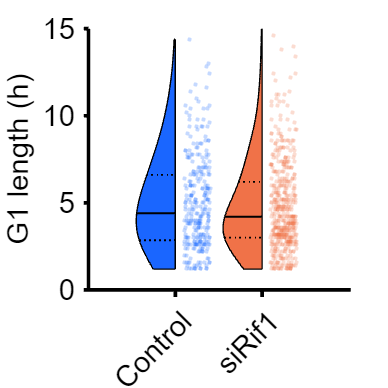


figure('Units', 'Inches', 'Position', [0, 0, 3, 3])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 5,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','siRif1'})
ylim([0 15])
 xtickangle(45)
axis square




p=mediantest(ally(groups==1),ally(groups==2))

p = 0.1000


% print_pdf(['fig_S4Bleft.svg'])

**S4B right**

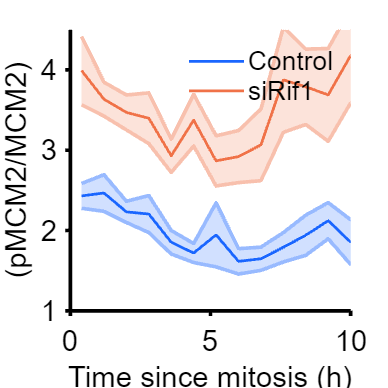

ans = 3834

ans = 7348

conds=[15 10] ;
poi_list = [1];
offset=0;

colors = [.1 .4 1;.941 .447 .282;.4 .1 .5; 0 .7 1];
   figure('Units', 'Inches', 'Position', [0, 0, 3, 3])
   hold on
gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'mitosis'};
edges = (0:(4/framesPerHr):24);
lims = {[0 10],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
        ind= ~isnan(S(conds(i)).POI_time(:,poiAligned));
           sum(ind)
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
         ydata(:, 1) = (S(conds(i)).iRFP1(ind)-170);
        ydata(:, 2) = log2(S(conds(i)).dna(ind));
        ydata(:, 3) = (S(conds(i)).YFP1(ind)-170);
        ydata(:,4) = ydata(:,3)./ydata(:,1);

        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);

        bin_gate = binData(4).numCells > 10;

       
        shadedErrorBar(midpoints(bin_gate), binData(4).mean(bin_gate), 2*binData(4).std(bin_gate)./sqrt(binData(4).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
           xlabel(['Time since ' name{p} ' (h)']);
        ylabel('(pMCM2/MCM2)');
        xlim(lims{p});
        ylim([1 4.5])
        axis square
        hold on
        
      
    end
    legend('Control', 'siRif1','box','off')
 % print_pdf(['fig_S3Bright.pdf'])

end